# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\MSIT\RawData'];              % Raw Data Folder Directory

% Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: [Akida@bu.edu](mailto:Akida@bu.edu)

Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = true;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\MSIT\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {5};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[12:19] [22:25] [37:39] [42:44]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [10 20 30 69 40 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {3};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {4};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []                                                                         % Add additionall Preprocessing Parameters as according to ft_preprocessing

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 5
        Proceed: 0
           PCom: 1
             DT: [1×1 struct]
             PP: [1×1 struct]


## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.RejectNans = true;
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

#### Time-Frequency Analysis

Deci.Analysis.Freq.do            = true;
Deci_Wavelet;
Deci.Analysis.Freq.foi           = unique([linspace(4,8,12) linspace(8,13,12) linspace(13,30,12) linspace(30,60,12)]);
Deci.Analysis.Freq.laplace = 0;
Deci.Analysis.Version = ['C:\Users\User\Desktop\MSIT\' 'ProcessedData'];

% Currently Unavailable
Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';

Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};  % can only currently handle '' or 'mi'(pac)
Deci.Plot.CFC.errorbars = true ;

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 20]};

Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [true];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

**General Set-Up**

Deci.Plot.Lock = 'MSIT Response Onset';
Deci.Plot.BslRef = 'MSIT Stim Onset';
Deci.Plot.GrandAverage = true;
Deci.Plot.FreqYScale = 'linear';

% Comment your CondTitles here so you can refer to them for Math and Draw
msit_plot_singleconds;
% Time-Frequency


#### Statistics

Deci.Plot.Stat.do = true;
Deci.Plot.Stat.Type = 'Anova/T-test';
Deci.Plot.Stat.alpha = .05;
Deci.Plot.Stat.fdr = false;
Deci.Plot.Stat.FPlots =  false;


#### Time-Frequency

Deci.Plot.Freq.Foi     = [8 12];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [-.5 .5];                   % Time of Interest
Deci.Plot.Freq.Channel = [{'P2' 'P3' 'P4' 'P5' 'Pz' 'POz'}];                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =false;
Deci.Plot.Freq.Square  =true;
Deci.Plot.Freq.Wire    =true;
Deci.Plot.Freq.Bar    =true;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =false;
Deci.Plot.ERP.Wire =false;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [true false];
Deci.Plot.Behv.Acc.Total = {{[1:16] [1:16]} {[1 5 9 13] [2 6 10 14] [3 7 11 15] [4 8 12 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1:8] [9:16]} {[1 5] [2 6] [3 7] [4 8]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {{'Opt Percent' 'Wst Percent'} {'AB' 'CD' 'EF' 'GH'}};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;


Deci.Plot.Behv.RT.Figure = [true false];
Deci.Plot.Behv.RT.Draw = {{[1:8] [9:16]}  {[1 5] [2 6] [3 7] [4 8] [9 13] [10 14] [11 15] [12 16]} {}};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials RT'};
Deci.Plot.Behv.RT.Subtitle = {{'Opt' 'Worst'} {'Opt AB' 'Opt CD' 'Opt EF' 'Opt GH' 'Wst AB' 'Wst CD' 'Wst EF' 'Wst GH'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## * 6. Run*

Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.090014 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.205797 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.317773 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.413808 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.073199 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.173342 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Channel POz of 6
Elapsed time is 0.271836 seconds.
Channel P2 of 6
Channel P3 of 6
Channel P4 of 6
Channel P5 of 6
Channel Pz of 6
Cha

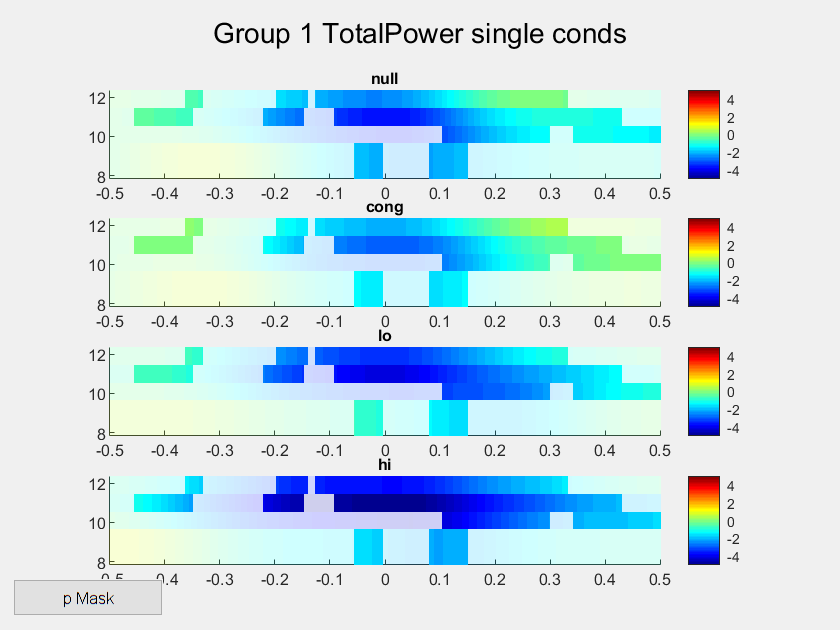

the call to "ft_singleplotTFR" took 0 seconds


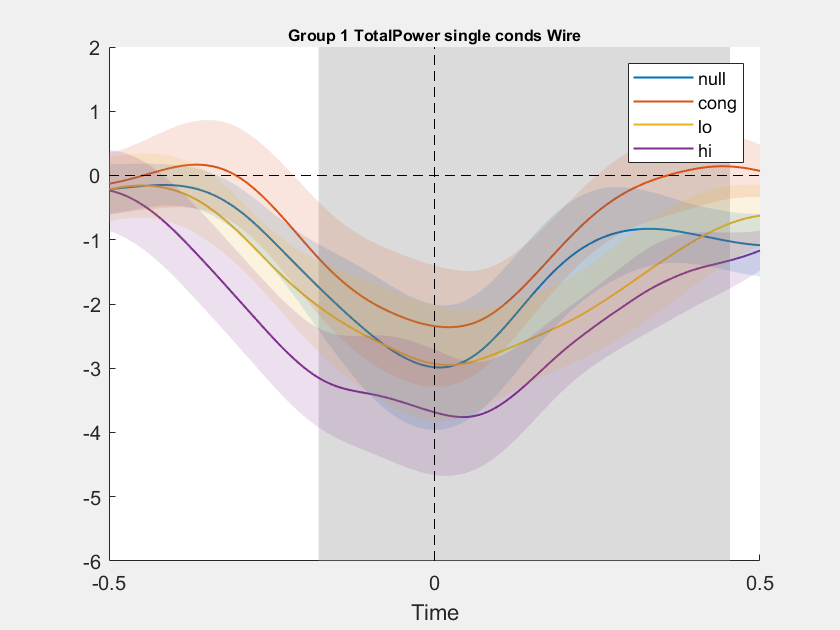

the call to "ft_singleplotTFR" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds
the call to "ft_singleplotER" took 0 seconds


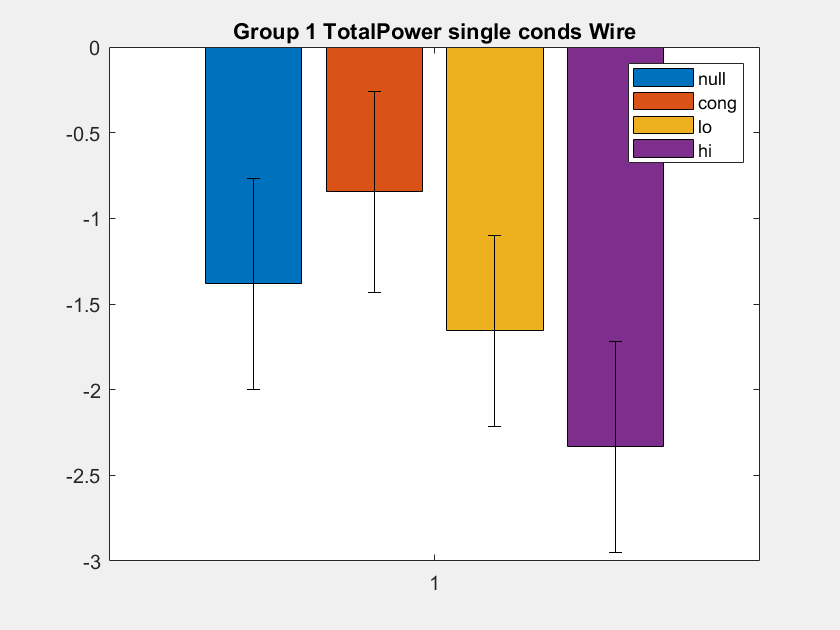

Deci_Backend(Deci);